# Work with Specialized ROS Messages

This example shows how to handle message types for:

- **uncompressed and compressed images, **

- **point clouds, **

- **quaternions**

- camera info, 

- laser scans, 

- occcupancy grid, and 

- octomap messages.

Make sure to at least cover images, point clouds, and quaternions. The rest can be for reference.

These are some commonly used ROS messages stored data in a format, that requires some transformation before they can be used for further processing. 

In this notebook,  you will come across many matlab helper functions to help format these specialized ROS messages for easy use in matlab.

## Load Sample Messages

Load some sample messages. These messages are populated with real and synthetic data from various robotics sensors.

load("specialROSMessageData.mat")

## Image Messages

Note: If you are not very familiar with images, check out Matlab's online training module ([https://matlabacademy.mathworks.com/details/computer-vision-onramp/orcv](https://matlabacademy.mathworks.com/details/computer-vision-onramp/orcv) ).

MATLAB provides support for image messages, which always have the message type `sensor_msgs/Image`.

Create an empty image message using [`rosmessage`](docid:ros_ref.bupf5_j_2) to see the standard ROS format for an image message. 

emptyimg = rosmessage("sensor_msgs/Image",DataFormat="struct")

emptyimg = struct with fields:
    MessageType: 'sensor_msgs/Image'
         Header: [1x1 struct]
         Height: 0
          Width: 0
       Encoding: ''
    IsBigendian: 0
           Step: 0
           Data: [0x1 uint8]


For convenience, an image message that is fully populated and is stored in the `img` variable is loaded from `specialROSMessageData.mat`.

Inspect the image message variable `img` in your workspace. The size of the image is stored in the `Width` and `Height` properties. ROS sends the actual image data using a vector in the `Data` property.

img

img = struct with fields:
    MessageType: 'sensor_msgs/Image'
         Header: [1x1 struct]
         Height: 480
          Width: 640
       Encoding: 'rgb8'
    IsBigendian: 0
           Step: 1920
           Data: [921600x1 uint8]


The `Data` property stores raw image data that cannot be used directly for processing and visualization in MATLAB. 

You can use the [rosReadImage](docid:ros_ref#buqbtm0) function to retrieve the image in a format that is compatible with MATLAB.

imageFormatted = rosReadImage(img);

The original image has a rgb8 encoding. 

By default, [rosReadImage](docid:ros_ref#buqbtm0) returns the image in a standard 480-by-640-by-3 `uint8` format. View this image using the [`imshow`](docid:matlab_ref.bvmnrxi-1) function.

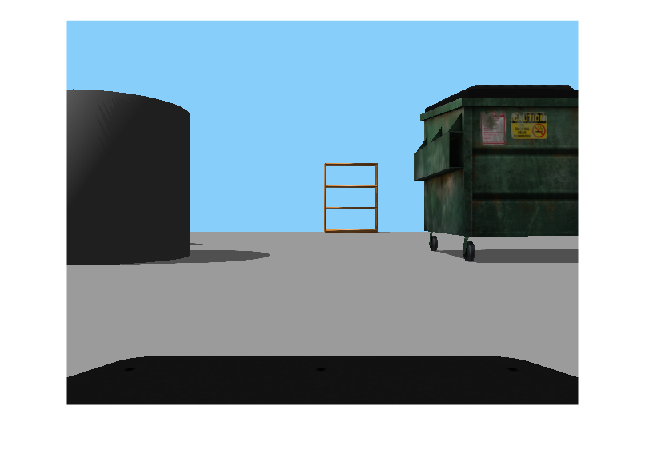

imshow(imageFormatted)

MATLAB® supports all ROS image encoding formats, and [rosReadImage](docid:ros_ref#buqbtm0) handles the complexity of converting the image data. In addition to color images, MATLAB also supports monochromatic and depth images.

Additionally, MATLAB provides the [rosWriteImage](docid:ros_ref#buqby1r-1) function to convert a MATLAB image to a ROS message using the function. 

Apply rudimentary object detection on the sample image with color thresholding. 

Visualize the modified image.  

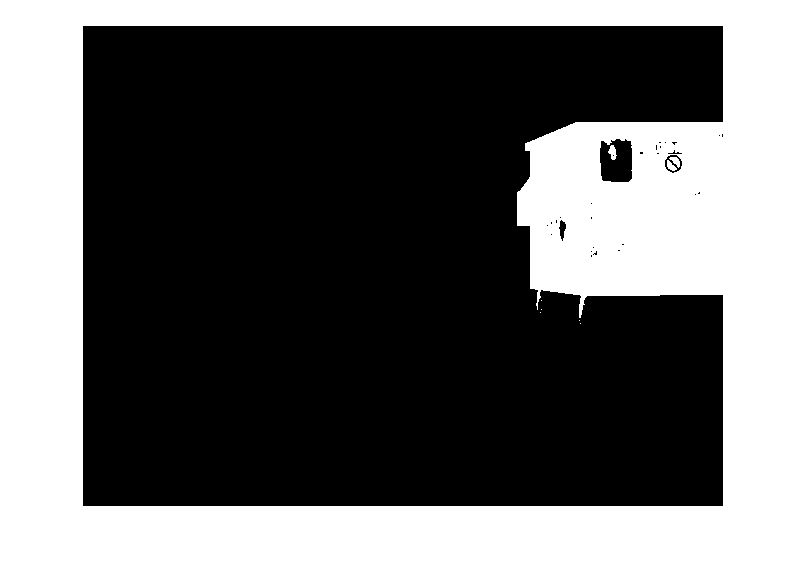

greenPercentage = 100*double( imageFormatted(:,:,2) )./sum(imageFormatted,3);
thresholdImg = 255*uint8(greenPercentage > 35);
imshow(thresholdImg)

Write the modified image to a ROS message with the [rosWriteImage](docid:ros_ref#buqby1r-1) function. 

Since the modified image only has 1 channel and is of type `uint8`, use the `mono8` encoding.    

imageMsg = rosWriteImage(emptyimg,thresholdImg, Encoding = "mono8");

## Compressed Image Messages

Many ROS systems send their image data in a compressed format. MATLAB provides support for these compressed image messages. 

Create an empty compressed image message using [`rosmessage`](docid:ros_ref.bupf5_j_2). 

Compressed images in ROS have the message type `sensor_msgs/CompressedImage` and have a standard structure.

emptyimgcomp = rosmessage("sensor_msgs/CompressedImage", DataFormat="struct")

emptyimgcomp = struct with fields:
    MessageType: 'sensor_msgs/CompressedImage'
         Header: [1x1 struct]
         Format: ''
           Data: [0x1 uint8]


For convenience, a compressed image message that is already populated was loaded from `specialROSMessageData.mat`.

Inspect the `imgcomp` variable that was captured by a camera. 

The `Format` property captures all the information that MATLAB needs to decompress the image data stored in `Data`.

imgcomp

imgcomp = struct with fields:
    MessageType: 'sensor_msgs/CompressedImage'
         Header: [1x1 struct]
         Format: 'bgr8; jpeg compressed bgr8'
           Data: [30376x1 uint8]


Similar to the image message, you can use [rosReadImage](docid:ros_ref#buqbtm0) to obtain the image in standard RGB format. 

Even though the original encoding for this compressed image is `bgr8`, [rosReadImage](docid:ros_ref#buqbtm0) does the conversion. 

compressedFormatted = rosReadImage(imgcomp);

Visualize the image using the [`imshow`](docid:matlab_ref.bvmnrxi-1) function.

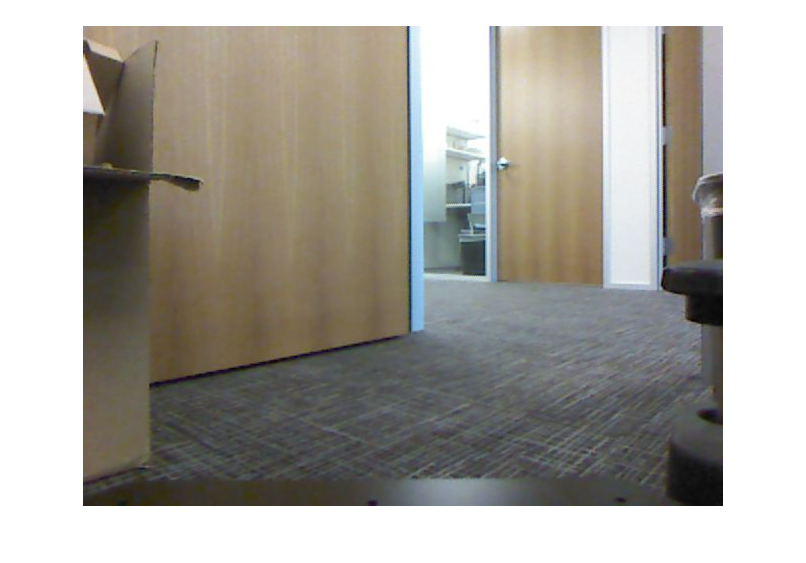

imshow(compressedFormatted)

Most image formats are supported for the compressed image message type. 

The `16UC1` and `32FC1` encodings are not supported for compressed depth images. Monochromatic and color image encodings are supported.

## Point Cloud Messages

Point clouds can be captured by a variety of sensors used in robotics, including LIDARs, Kinect®, and stereo cameras. The most common message type in ROS for transmitting point clouds is `sensor_msgs/PointCloud2` and MATLAB provides some specialized functions for you to work with this data.

You can see the standard ROS format for a point cloud message by creating an empty point cloud message.

emptyptcloud = rosmessage("sensor_msgs/PointCloud2",DataFormat="struct")

emptyptcloud = struct with fields:
    MessageType: 'sensor_msgs/PointCloud2'
         Header: [1x1 struct]
         Height: 0
          Width: 0
         Fields: [0x1 struct]
    IsBigendian: 0
      PointStep: 0
        RowStep: 0
           Data: [0x1 uint8]
        IsDense: 0


View the populated point cloud message that is stored in the `ptcloud` variable in your workspace:

ptcloud

ptcloud = struct with fields:
    MessageType: 'sensor_msgs/PointCloud2'
         Header: [1x1 struct]
         Height: 480
          Width: 640
         Fields: [4x1 struct]
    IsBigendian: 0
      PointStep: 32
        RowStep: 20480
           Data: [9830400x1 uint8]
        IsDense: 0


The point cloud information is encoded in the `Data` property of the message. You can extract the *x*`,`*y*`,`*z* coordinates as an *N*-by-3 matrix by calling the [rosReadXYZ](docid:ros_ref#buqbra8) function.

xyz = rosReadXYZ(ptcloud)

xyz = 307200x3 single matrix
   NaN   NaN   NaN
   NaN   NaN   NaN
   NaN   NaN   NaN
   NaN   NaN   NaN
   NaN   NaN   NaN
   NaN   NaN   NaN
   NaN   NaN   NaN
   NaN   NaN   NaN
   NaN   NaN   NaN
   NaN   NaN   NaN


`NaN` in the point cloud data indicates that some of the *x*`,`*y*`,`*z* values are not valid. This is an artifact of the Kinect® sensor, and you can safely remove all `NaN` values.

xyzValid = xyz(~isnan(xyz(:,1)),:)

xyzValid = 193359x3 single matrix
    0.1378   -0.6705    1.6260
    0.1409   -0.6705    1.6260
    0.1433   -0.6672    1.6180
    0.1464   -0.6672    1.6180
    0.1502   -0.6705    1.6260
    0.1526   -0.6672    1.6180
    0.1556   -0.6672    1.6180
    0.1587   -0.6672    1.6180
    0.1618   -0.6672    1.6180
    0.1649   -0.6672    1.6180


Some point cloud sensors also assign RGB color values to each point in a point cloud. If these color values exist, you can retrieve them with a call to [rosReadRGB](docid:ros_ref#buqbpn2).

rgb = rosReadRGB(ptcloud)

rgb = 307200x3 single matrix
    0.8392    0.7059    0.5255
    0.8392    0.7059    0.5255
    0.8392    0.7137    0.5333
    0.8392    0.7216    0.5451
    0.8431    0.7137    0.5529
    0.8431    0.7098    0.5569
    0.8471    0.7137    0.5569
    0.8549    0.7098    0.5569
    0.8588    0.7137    0.5529
    0.8627    0.7137    0.5490


You can visualize the point cloud with the `rosPlot` function. [rosPlot](docid:ros_ref#buqbjtl) automatically extracts the *x*`,`*y*`,`*z* coordinates and the RGB color values (if they exist) and show them in a 3-D scatter plot. The `rosPlot` function ignores all `NaN` *x*`,`*y*`,`*z* coordinates, even if RGB values exist for that point.

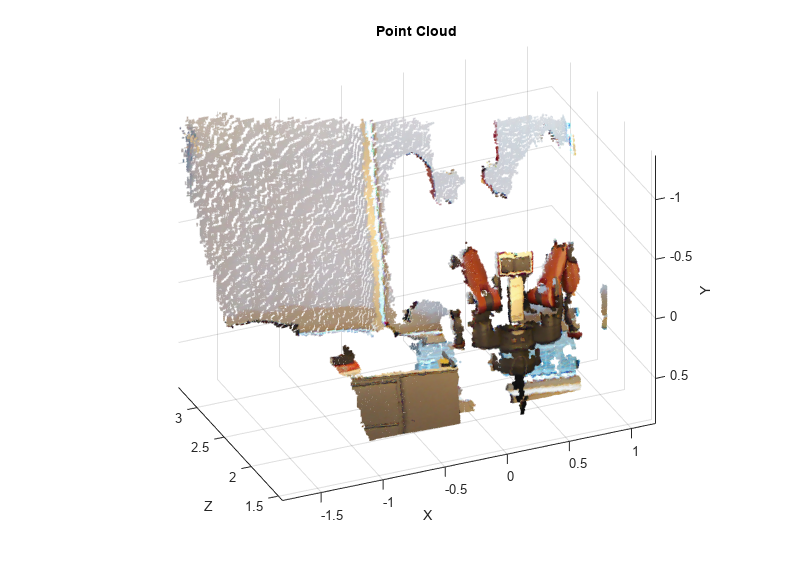

rosPlot(ptcloud)

Examine all the stored fields in the point cloud message using the [rosReadAllFieldNames](docid:ros_ref#buqbkiq) function. The loaded point cloud message contains four fields `x`, `y`, `z`, and `rgb`.    

fieldNames = rosReadAllFieldNames(ptcloud)

fieldNames = 1x4 cell array
    {'x'}    {'y'}    {'z'}    {'rgb'}


You can access the corresponding data for any field using the [rosReadField](docid:ros_ref#buqbota) function. You must unpack the returned data manually, depending on how it is formatted. For example, the RGB image can be extracted by type casting the data to `uint8` and reshaping the result. Use the result from the [rosReadAllFieldNames](docid:ros_ref#buqbkiq) function for input validation.          

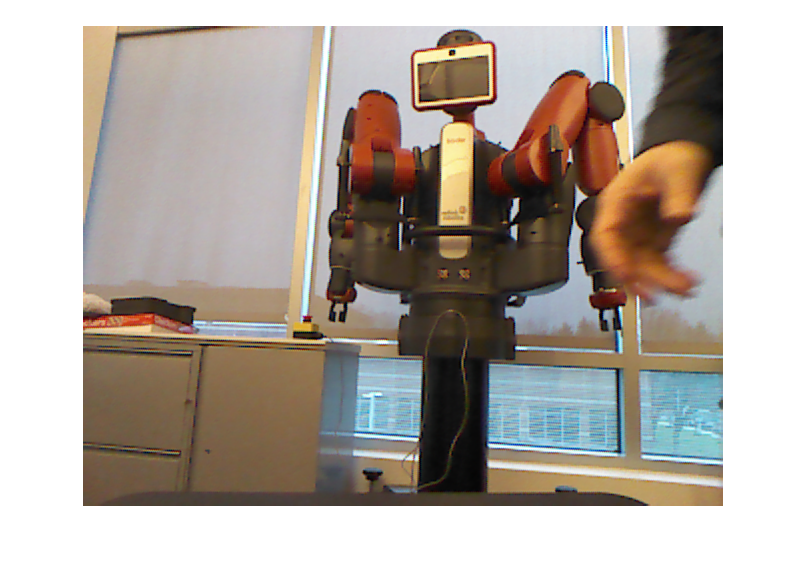

if any(contains(fieldNames,"rgb"))
    rawData = typecast(rosReadField(ptcloud,"rgb"),"uint8");
    tmp = reshape(permute(reshape(rawData,4,[]),[3,2,1]),ptcloud.Width,ptcloud.Height,4);
    pcImg = permute(tmp(:,:,[3,2,1]),[2 1 3]);
    imshow(pcImg)
end

Calculate the intensity value of each point in the point cloud as `1/3(r+g+b)`, where r, g, and b are the RGB color values of that point, respectively.

intensity = sum(rgb,2)/3;

Write the *x, y, z,* RGB, and intensity values to the empty point cloud message using [`rosWriteXYZ`](docid:ros_ref#mw_72ca0224-0461-4e53-a12c-61e8d6708666), [`rosWriteRGB`](docid:ros_ref#mw_77a4e46e-0ba7-4a3a-bae0-5dd8484bb51e), and [`rosWriteIntensity`](docid:ros_ref#mw_ee1670f0-d729-4143-a185-6de738779197) functions respectively. Specify a point step size of `32`.

ptcloudWithIntensity = rosWriteXYZ(emptyptcloud,xyz,PointStep=uint32(32));
ptcloudWithIntensity = rosWriteRGB(ptcloudWithIntensity,rgb);
ptcloudWithIntensity = rosWriteIntensity(ptcloudWithIntensity,intensity)

ptcloudWithIntensity = struct with fields:
    MessageType: 'sensor_msgs/PointCloud2'
         Header: [1x1 struct]
         Height: 1
          Width: 307200
         Fields: [5x1 struct]
    IsBigendian: 0
      PointStep: 32
        RowStep: 9830400
           Data: [9830400x1 uint8]
        IsDense: 0


## Quaternion Messages

Quaternions are commonly used in robotics to express orientation. Use [`rosmessage`](docid:ros_ref.bupf5_j_2) to create a quaternion message and observe the fields.

emptyquatmsg = rosmessage("geometry_msgs/Quaternion",DataFormat="struct")

emptyoctomap = struct with fields:
    MessageType: 'octomap_msgs/Octomap'
         Header: [1x1 struct]
         Binary: 0
             Id: ''
     Resolution: 0
           Data: [0x1 int8]


For convenience, a quaternion message that represents a 90 degree rotation about the z-axis was loaded from `specialROSMessageData.mat`. Inspect the variable `quatMsg` in your workspace.

quatmsg

octomap = struct with fields:
    MessageType: 'octomap_msgs/Octomap'
         Header: [1x1 struct]
         Binary: 1
             Id: 'OcTree'
     Resolution: 0.0250
           Data: [3926x1 int8]


Create a `quaternion` object from a ROS message using the [rosReadQuaternion](docid:ros_ref#mw_85347c7d-e517-4a81-9e5d-390b49508371) function. The `quaternion` object contains the x, y, z, and w components and provides additional functionalities, such as rotating a point.

quat = rosReadQuaternion(quatmsg);

Define a point in three-dimensional space and rotate it using `rotatepoint` function. Visualize the two points

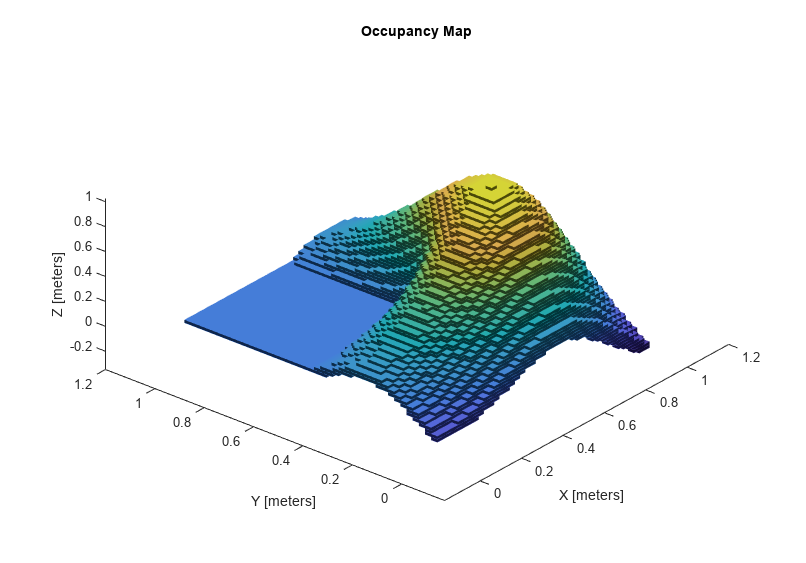

cartesianPoint = [1,0,1];


% Draw a point on the Cartesian point
plot3(cartesianPoint(1),cartesianPoint(2),cartesianPoint(3),"bo")

% Draw a line from the origin to the cartesianPoint
hold on; plot3([0;cartesianPoint(1)],[0;cartesianPoint(2)],[0;cartesianPoint(3)],"k")

emptycamerainfomsg = struct with fields:
        MessageType: 'sensor_msgs/CameraInfo'
             Header: [1x1 struct]
             Height: 0
              Width: 0
    DistortionModel: ''
                  D: [0x1 double]
                  K: [9x1 double]
                  R: [9x1 double]
                  P: [12x1 double]
           BinningX: 0
           BinningY: 0
                Roi: [1x1 struct]



% Rotate the poitn by the quaternion
rotationResult = rotatepoint(quat,cartesianPoint);

% Plot the newly rotated point
plot3(rotationResult(1),rotationResult(2),rotationResult(3),"ro")

% Plot the line from the origin to the rotated point
plot3([0;rotationResult(1)],[0;rotationResult(2)],[0;rotationResult(3)],"k")

% Add labels and grid
xlabel("x"), ylabel("y"), zlabel("z"), grid on

## Octomap Messages

ROS uses Octomap messages to implement 3D occupancy grids. Octomap messages are commonly used in robotics applications, such as 3D navigation**. **You can see the standard ROS format for an octomap message by creating an empty message of the appropriate type. 

Use [`rosmessage`](docid:ros_ref.bupf5_j_2) to create the message.

emptyoctomap = rosmessage("octomap_msgs/Octomap",DataFormat="struct")

ans = 5x2 table
                             ROS message      camera parameters   
                             ___________    ______________________

    Intrinsic matrix          "K"           "IntrinsicMatrix"     
    Radial distortion         "D(1:2)"      "RadialDistortion"    
    Tangential distortion     "D(3:5)"      "TangentialDistortion"
    Height                    "Height"      "ImageSize(1)"        
    Width                     "Width"       "ImageSize(2)"        


For convenience, an `octomap` message that is fully populated and is stored in the `octomap` variable loaded from `specialROSMessageData.mat.`

Inspect the variable `octomap` in your workspace. The `Data` field contains the octomap structure in a serialized format.

octomap

K =   714.1885         0  563.6481
         0  710.3785  355.7254
         0         0    1.0000


Create an [`occupancyMap3D`](docid:nav_ref#mw_3607daa5-c0a8-4e07-9dff-a0b8679e0e6d) object from the ROS message using the [rosReadOccupancyMap3D](docid:ros_ref#mw_936ca20c-8ee3-4bc4-9d42-297c401d96ec) function. Display the 3D occupancy map using the `show` function.

occupancyMap3DObj = rosReadOccupancyMap3D(octomap);

intrinsicMatrix =   714.1885         0  563.6481
         0  710.3785  355.7254
         0         0    1.0000


show(occupancyMap3DObj)

## Camera Info Messages

Camera calibration is a commonly used procedure in robotics vision applications. ROS provides `sensor_msgs/CameraInfo` message type to publish calibration information. Use [`rosmessage`](docid:ros_ref.bupf5_j_2) to create a camera info message and observe the fields.

emptycamerainfomsg = rosmessage("sensor_msgs/CameraInfo",DataFormat="struct")

Notably, the message stores the matrices `K` and `P` as vectors. ROS requires these matrices to be stored in row-major format. MATLAB stores matrices in column-major, hence extracting the `K` and `P` matrices requires reshaping and transposing.    

The [`estimateCameraParameters`](docid:vision_ref#btyke8p-1) function can be used to create [`cameraParameters`](docid:vision_ref#mw_16529767-1343-428e-9c2a-3324fcf00d5a) and [`stereoParameters`](docid:vision_ref#bt8mdmz-1) objects. You can create `sensor_msgs/CameraInfo` messages from these objects using the `rosWriteCameraInfo` function. The objects must be converted to structures before use. Load the camera calibration structures.

load("calibrationStructs.mat")

ans = 2x2 table
                               ROS message          stereoParameters      
                               ____________    ___________________________

    Translation of camera 2    "P(:,1:2)"      "TranslationOfCamera2(1:2)"
    Rotation of camera 2       "inv(R1)*R2"    "RotationOfCamera2"        


For convenience, the variable `params` loaded from `calibrationStructs.mat` is a fully populated `cameraParameters` struct. Write the `cameraParameters` struct to a new ROS message using the `rosWriteCameraInfo` function.

msg = rosWriteCameraInfo(emptycamerainfomsg,params);

The following table shows the correspondence between the cameraParameters object and the ROS message. 

exampleHelperShowCameraParametersTable

Verify that the intrinsic matrix of the ROS message matches the intrinsic matrix of `params`. 

 K = reshape(msg.K,3,3)'

R =     1.0000   -0.0002   -0.0050
    0.0002    1.0000   -0.0037
    0.0050    0.0037    1.0000


 intrinsicMatrix = params.IntrinsicMatrix'

rotationOfCamera2 =     1.0000   -0.0002   -0.0050
    0.0002    1.0000   -0.0037
    0.0050    0.0037    1.0000


For convenience, the variable `stereoParams` loaded from `calibrationStructs.mat` is a fully populated `stereoParameters` struct. Write the `stereoParameters` struct to two new ROS messages using the `rosWriteCameraInfo` function.

[msg1,msg2] = rosWriteCameraInfo(msg,stereoParams);

The following table shows the correspondence between the stereoParameters object and the ROS message. 

exampleHelperShowStereoParametersTable

ans =  -119.8720   -0.4005


Verify that the camera 2 rotation matrices of the ROS message and `stereoParams` match.  

R1 = reshape(msg1.R,3,3)';

translationOfCamera2 =  -119.8720   -0.4005


R2 = reshape(msg2.R,3,3)';
R = R1\R2
rotationOfCamera2 = stereoParams.RotationOfCamera2

Verify that the camera 2 translation vectors of the ROS message and `stereoParams` match.  

P = reshape(msg2.P,4,3)';

emptyscan = struct with fields:
       MessageType: 'sensor_msgs/LaserScan'
            Header: [1x1 struct]
          AngleMin: 0
          AngleMax: 0
    AngleIncrement: 0
     TimeIncrement: 0
          ScanTime: 0
          RangeMin: 0
          RangeMax: 0
            Ranges: [0x1 single]
       Intensities: [0x1 single]


P(1:2,end)'
translationOfCamera2 = stereoParams.TranslationOfCamera2(1:2)

## Laser Scan Messages

Laser scanners are commonly used sensors in robotics. ROS provides `sensor_msgs/LaserScan` message type to publish laser scan messages. Use [`rosmessage`](docid:ros_ref.bupf5_j_2) to create a laser scan message and observe the fields.

emptyscan = rosmessage("sensor_msgs/LaserScan","DataFormat","struct")

scan = struct with fields:
       MessageType: 'sensor_msgs/LaserScan'
            Header: [1x1 struct]
          AngleMin: -0.5467
          AngleMax: 0.5467
    AngleIncrement: 0.0017
     TimeIncrement: 0
          ScanTime: 0.0330
          RangeMin: 0.4500
          RangeMax: 10
            Ranges: [640x1 single]
       Intensities: [0x1 single]


Since you created an empty message, `emptyscan` does not contain any meaningful data. For convenience, a laser scan message that is fully populated and is stored in the `scan` variable was loaded from `specialROSMessageData.mat`.

Inspect the `scan` variable. The primary data in the message is in the `Ranges` property. The data in `Ranges` is a vector of obstacle distances recorded at small angle increments.

scan

You can get the scan angles from the ROS message using the [rosReadScanAngles](docid:ros_ref#bus65fa-1) function. Visualize the scan data in polar coordinates using the `polarPlot` function.  

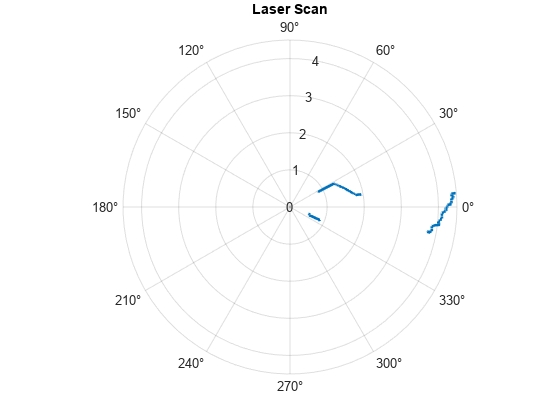

angles = rosReadScanAngles(scan);
figure
polarplot(angles,scan.Ranges,LineWidth=2)

title("Laser Scan")

You can get the measured points in Cartesian coordinates using the [rosReadCartesian](docid:ros_ref#buqbmq9) function.

xy = rosReadCartesian(scan);

This populates `xy` with a list of `[x,y]` coordinates that were calculated based on all valid range readings. Visualize the scan message using the [rosPlot](docid:ros_ref#buqbjtl) function:

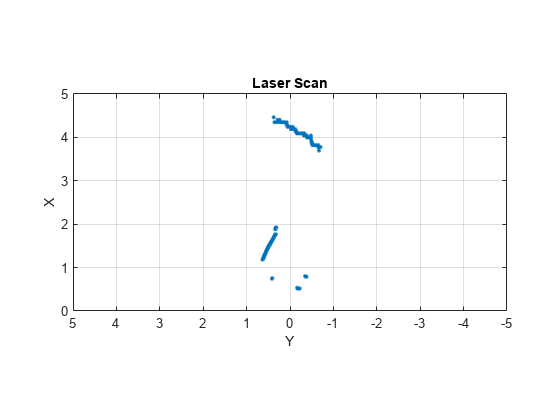

rosPlot(scan,"MaximumRange",5)

Create a `lidarScan` object from a ROS message using the [rosReadLidarScan](docid:ros_ref#mw_0b6f3410-6381-43f3-bb07-1e0957143a42) function. The `lidarScan` object contains ranges, angles, and Cartesian points and provides additional functionalities, such as transforming the scanned points. Use the `transformScan` function to rotate the scan point and visualize it using `plot`.        

lidarScanObj = rosReadLidarScan(scan)

lidarScanObj =   lidarScan with properties:

       Ranges: [640x1 double]
       Angles: [640x1 double]
    Cartesian: [640x2 double]
        Count: 640


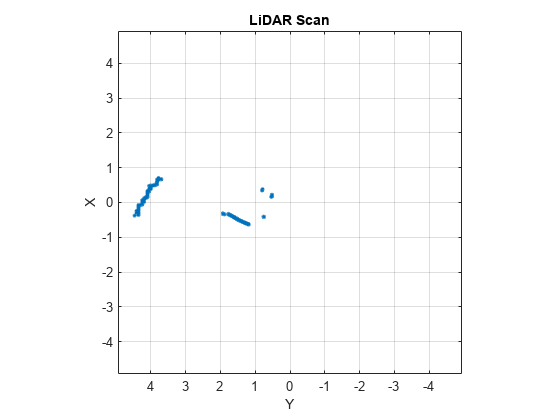

rotateScan = transformScan(lidarScanObj,[0,0,pi/2]);
plot(rotateScan)

## Occupancy Grid Messages

Occupancy grid messages are commonly used in robotics for 2D navigation applications**. **ROS provides `nav_msgs/OccupancyGrid` message type to publish occupancy grid messages. Use [`rosmessage`](docid:ros_ref.bupf5_j_2) to create an occupancy grid message and observe the fields.

emptyMap = rosmessage("nav_msgs/OccupancyGrid",DataFormat="struct")

emptyMap = struct with fields:
    MessageType: 'nav_msgs/OccupancyGrid'
         Header: [1x1 struct]
           Info: [1x1 struct]
           Data: [0x1 int8]


Notice that `emptyMap` does not contain any meaningful data. For convenience, an occupancy grid message that is fully populated and is stored in the `mapMsg` variable loaded from `specialROSMessageData.mat.`

Inspect the `mapMsg` variables. The occupancy grid values are encoded in the `Data` field.

mapMsg

mapMsg = struct with fields:
    MessageType: 'nav_msgs/OccupancyGrid'
         Header: [1x1 struct]
           Info: [1x1 struct]
           Data: [251001x1 int8]


Use the [`rosReadOccupancyGrid`](docid:ros_ref#mw_e397bdb0-7aad-4dd5-b6d0-b771237a4841) function to convert the ROS message to an [`occupancyMap`](docid:nav_ref#bvaw60t-1) object. Use the `show` function to display the occupancy grid.

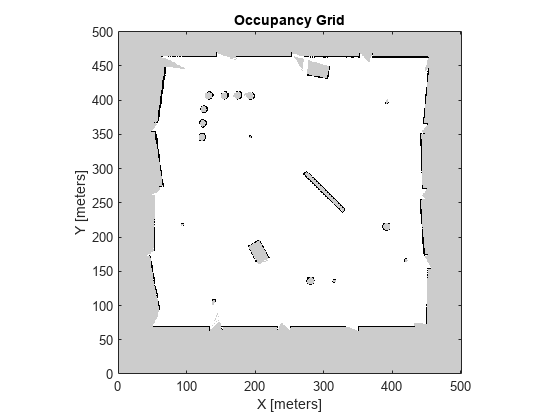

occupancyMapObj = rosReadOccupancyGrid(mapMsg);
show(occupancyMapObj);

You can use the [`occupancyMap`](docid:nav_ref#bvaw60t-1) object functions to manipulate the occupancy grid. Use the `inflate` function to expand the occupied regions. Write the occupancyMap object to a new ROS message using the [rosWriteOccupancyGrid](docid:ros_ref#mw_9d4a4cde-15d2-4810-a7e9-e8f4c078ce9c) function. Use the `show` function to display the new occupancy grid.

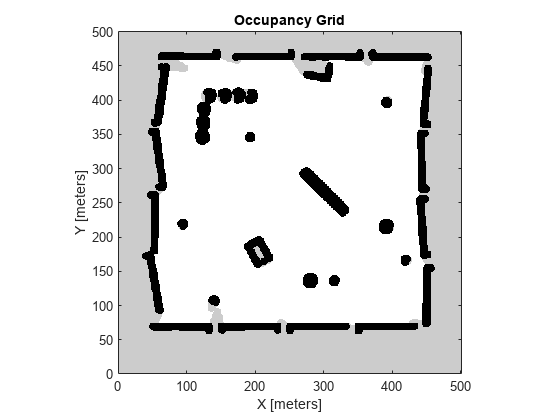

inflate(occupancyMapObj,5)
occupancyMapInflatedMsg = rosWriteOccupancyGrid(mapMsg,occupancyMapObj);
show(occupancyMapObj);

Alternatively, you can create a [`binaryOccupancyMap`](docid:nav_ref#bunq527) object from a ROS occupancy grid message using the [`rosReadBinaryOccupancyGrid`](docid:ros_ref#buqblh_) function. A binary occupancy map holds discrete occupancy values of `0` or `1` at each cell whereas an occupancy map holds probability occupancy values that range between `0` and `1` at each cell. Use the `show` function to display the binary occupancy grid.  

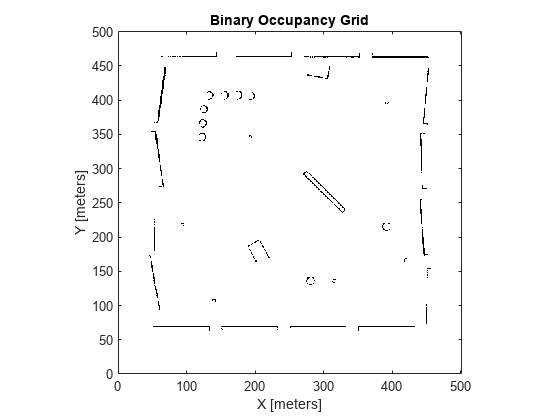

binaryMapObj = rosReadBinaryOccupancyGrid(mapMsg);
show(binaryMapObj);

Similarly, you can use the [`binaryOccupancyMap`](docid:nav_ref#bunq527) object functions to manipulate the binary occupancy grid. Use the `inflate` function to alter the binary occupancy grid and create a new ROS message using the [`rosWriteBinaryOccupancyGrid`](docid:ros_ref#buqbl58) function. Use the `show` function to display the new binary occupancy grid. 

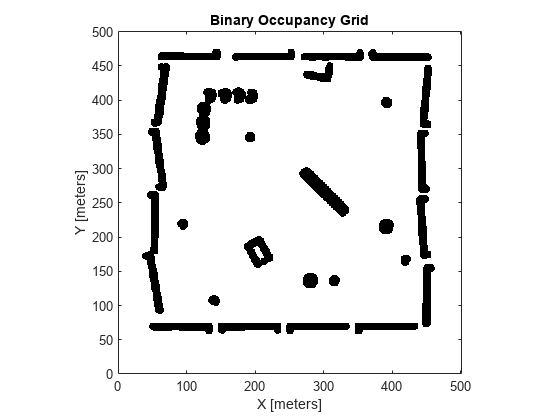

inflate(binaryMapObj,5)
binaryMapInflatedMsg = rosWriteBinaryOccupancyGrid(mapMsg,binaryMapObj);
show(binaryMapObj);

*Copyright 2014-2022 The MathWorks, Inc.*